# Ballbot robust stability analysis and validation script

**Contents:**

- Nonlinear model synthesis with distrubances

- Parametric linearisation 

- Parametric uncertainty introduction

- optimisation based worst case search

- Disturbance rejection and noise attenutation

- H-infinity controller synthesis

- based on linear systems 

- based on worst case system

- Comparison of behavior with nonlinear model

clear all

mkdir('generated')
addpath('./generated')
addpath('./visualisation')
addpath('./optimisation')

## Model physical parameters definition

Introducing the physical parameters of the system

global rK_n rW_n  rA_n  l_n  mAW_n mK_n  A_ThetaAWx_n  A_ThetaAWy_n  A_ThetaAWz_n  ThetaKi_n  ThetaWi_n;

% Uncertain parameters
rK_n = 0.120; % radius of the ball
rW_n = 0.05; % radius of omni wheel=5cm
rA_n = 0.126; % radius of the body  
l_n = 0.22634; % distance between centre of ball and centre of gravity of the body 
mAW_n = 6.71; % mass of the body and omni wheel  
mK_n = 0.625; % mass of the basket ball  
A_ThetaAWx_n = 1.41271413; % Inertia of the body and Omni wheels in the body reference frame A  
A_ThetaAWy_n = 1.41271311;
A_ThetaAWz_n = 0.05359646;
ThetaKi_n = 0.003606375;
ThetaWi_n = 0.01504; 

% Angle of motors
alpha = 47*pi/180;
beta1 = 0;
beta2 = 2/3*pi;
beta3 = 4/3*pi;

% vector of nominal parameters
params_n = [rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n];

## Derivation script of the nonlinear model

Modeling ot the nonlinear system - extended matlab version of the script FInal.nb made in Mathematica

- Parametric nonlinear model creation

- Linearization around 0

- Creation of simulation functions for further analyisis - linear and nonlinear

Execution can take 5-10 minutes

model_generation;

## Linear nominal model sysnthesys

Creation of linear transfer funciton based on linearised matrices of the Ballbot and the nominal parameters

Additionally the LQR controller is provided (based on the LQR controller in the report) as a default controller to be compared in further analysis.


% A matrix
tic
A_n= fA(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('A matrix :  %f sec\n',toc);

A matrix :  0.486393 sec


% B matrix
tic
B_n= fB(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B matrix :  %f sec\n',toc);

B matrix :  1.356716 sec


% B_w matrix
tic
B_w= fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B_w matrix :  %f sec\n',toc);

B_w matrix :  0.397626 sec



% state space model from matrices
G_n = ss(A_n, B_n, eye(10), zeros(10,3));


LQR controller synthesis


% LQR controller design
Q = diag([100 50 100 50 40 20 20 10 20 10]);
R = diag([100 100 100]);
K_lqr = lqr(G_n,Q,R);

## Linear and nonlinear model initial condition response comparison

Finally, simple graph of initial condition response for linear and nonlinear system with nominal parameters to see how well does the lienarized system corespond with the nonlinear

nonlinear system simulation
Nonlinear simulation: 4.00 sec / 4.00 sec
Elapsed time is 32.704546 seconds.
lienar system simulation
Elapsed time is 0.490189 seconds.


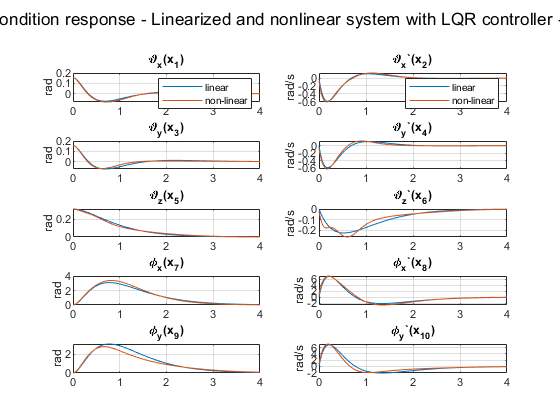

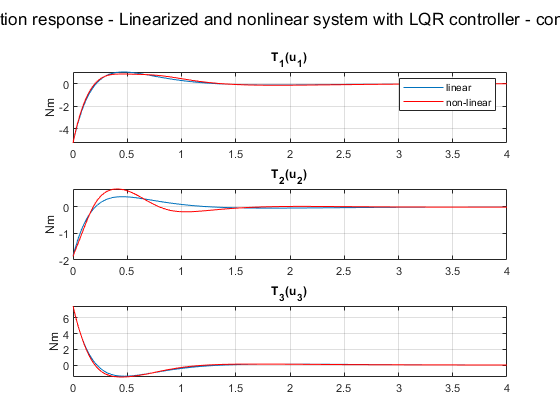

X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_max = 4; %s
initialplot_compare_nlin(@nlin_model_n,G_n,K_lqr,X0,T_max,1,2)

drawnow

## Introducing the uncertainties

The uncertainties are introduced into the physiscal parameters of the system. The idea is that for the variables you cannot measure you should have some uncertainty about their values. 

The uncertainties are set as the percentage. For example if l_var is 20, that means that your height of center of mass can be +-20% different than your nominal value.

% Uncertain variation of the parameters
l_var = 20; % percent
A_ThetaAWx_var = 20; % percent
A_ThetaAWy_var = 20; % percent
A_ThetaAWz_var = 20;% percent
ThetaKi_var = 20;% percent
ThetaWi_var = 20;% percent

% sample the uncertain models
kill_figures([100,101]);

Figure 100 not opened
Figure 101 not opened


Sample uncertain models
Uncertain model visualisation - initial condition response
It may take few minutes


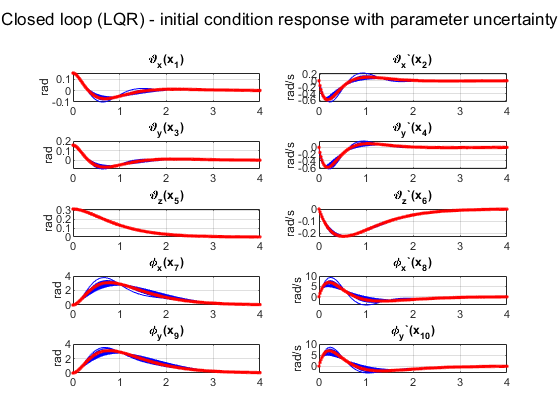

Elapsed time is 11.284673 seconds.
Uncertain model visualisation - singular value plot
It may take few minutes


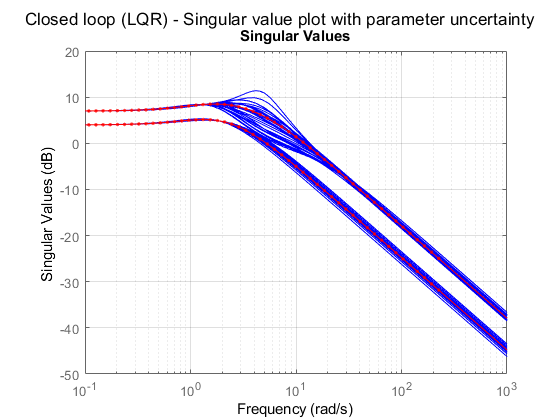

Elapsed time is 17.223617 seconds.


visualise_uncertainty(l_var, ThetaWi_var, ThetaKi_var, A_ThetaAWx_var, A_ThetaAWy_var, A_ThetaAWz_var, K_lqr,100,101);

## Find the worst case system based on parameter uncertainties

To be able to find the worst case parameters we define the optimisation problem based on disk margin. 

Basically we are changing the parameter values and searching to the minimum of the stability margin (diskmargin)

The minimal margin corresponds to the worst case parameters

wcu = find_wcu_optimisation(l_var, ThetaWi_var, ThetaKi_var, A_ThetaAWx_var, A_ThetaAWy_var, A_ThetaAWz_var, K_lqr)

Constrained optimisation approach to finding worst case condition

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      7     0.113707     -0.02158                                         
    1     14    0.0703206            0            1       -0.246        0.128   
    2     21     0.033049            0            1       -0.142        0.146   
    3     28    0.0329639            0            1      -0.0955       0.0858  Hessian modified  
    4     40    0.0329636            0       0.0313      -0.0374       0.0324   
    5     47    0.0329501            0            1     -0.00704      0.00892   
    6     54      0.03294            0            1     -0.00281        0.007  Hessian modified  
    7     61     0.032875            0            1     -0.00327        0.075  Hessian modified twice  
    8     68    0.0327953            0            1     -0.00

X =     0.8000    1.2000    0.8000    1.0105    1.2000    0.8997


FVAL = 0.0326

EXITFLAG = 5

Construct the worst case sample


wcu = struct with fields:
             l: 0.1811
       ThetaWi: 0.0180
       ThetaKi: 0.0029
    A_ThetaAWx: 1.4276
    A_ThetaAWy: 1.6953
    A_ThetaAWz: 0.0482
    min_margin: 0.0326
             G: [10×3 ss]
      max_gain: 12.4946


% variable wcu contains 
% wcu.l,ThetaKi,... - the worst case parameters 
% wcu.min_margin    - worst case margin
% wcu.max_gain      - worst case gain
% wcu.G             - linear state space model of the worst case transfer function


## Nominal and worst case linear model comparison

#### Margin comparison

% nominal parameters
MMIO_n = diskmargin(G_n,K_lqr)

MMIO_n = struct with fields:
     GainMargin: [0.8536 1.1715]
    PhaseMargin: [-9.0299 9.0299]
     DiskMargin: 0.1579
     LowerBound: 0.1579
     UpperBound: 0.1582
      Frequency: 3.5389


%worst case parameters
MMIO_wc = diskmargin(wcu.G,K_lqr)

MMIO_wc = struct with fields:
     GainMargin: [0.9679 1.0331]
    PhaseMargin: [-1.8665 1.8665]
     DiskMargin: 0.0326
     LowerBound: 0.0326
     UpperBound: 0.0326
      Frequency: 4.4068


#### Initial condition response

 % initialplot
X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_sim = 3; %sec=
kill_figures([110])

Figure 110 not opened


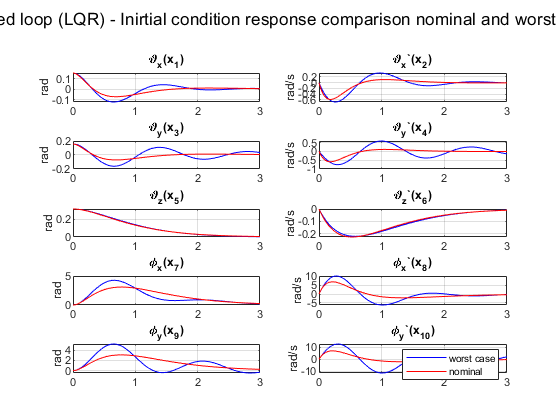

initialplt(feedback(wcu.G,K_lqr),'b',X0,T_sim,110); 
initialplt(feedback(G_n,K_lqr),'r',X0,T_sim,110);
legend('worst case','nominal')
sgtitle('Closed loop (LQR) - Inirtial condition response comparison nominal and worst case')

#### Singular value plota

kill_figures([111]);

Figure 111 not opened


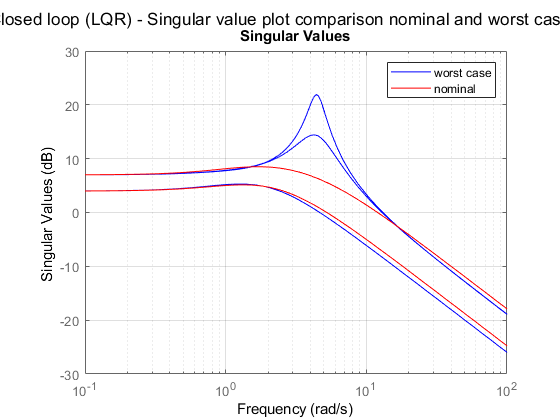

figure(111);
sigma(feedback(wcu.G,K_lqr),'b');
hold on;
sigma(feedback(G_n,K_lqr),'r');
legend('worst case','nominal')
grid on;
sgtitle('Closed loop (LQR) - Singular value plot comparison nominal and worst case')

## Validate worst case performance with the nonlinear model

Interesting is to see if nonlinear system is still stable for worst case parameters and LQR controller calculated for the nominal parameters.

% generate the worst  case parameters nonlinear model ans save it to  nlin_model_wcu function
model_generation_worst_case;

Creating a matlab function from nonlinear model
This may take few minutes
Writing function in the file
Elapsed time is 81.293583 seconds.


kill_figures([120,121]);

Figure 120 not opened
Figure 121 not opened


% Simulate and compare worst case linear and nonliner
initialplot_compare_nlin(@nlin_model_wcu,wcu.G,K_lqr,X0,T_sim,120,121)

nonlinear system simulation
Nonlinear simulation: 3.00 sec / 3.00 sec
Elapsed time is 31.583506 seconds.
lienar system simulation
Elapsed time is 0.108375 seconds.


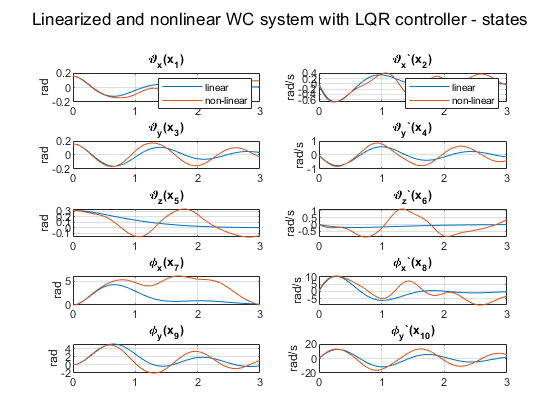

figure(120);
sgtitle('Linearized and nonlinear WC system with LQR controller - states')

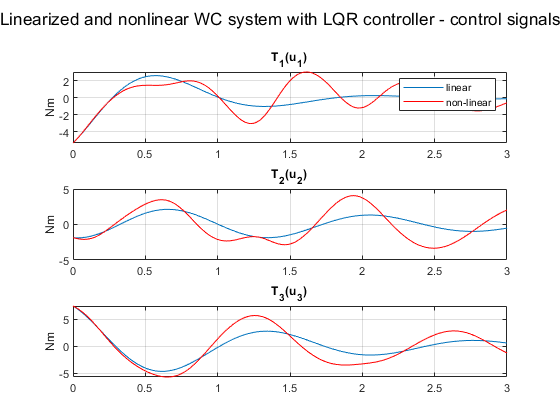

figure(121);
sgtitle('Linearized and nonlinear WC system with LQR controller - control signals')
drawnow

# Distrubance rejection and noise attenuation

#### **Ballbot has two type of disturbance **

 - ***force acting on the body - hunam interaction ****(w)*

 - ***measurement noise *** (*n*)

   > acceletometer and gyro

   > influences thetax, d_thetax, thetay, d_thetay  

#### ** Ballbot system**

 dx = Ax + [B_n B_w B_u]*[w n u]'

 y = Cx + [D_n D_w D_u]*[w n u]'

 u = K*x

% definining the standardized testing input for distrubance rejection
t_d = linspace(0,20,2000);
N_d = length(t_d);
n = randn(4,N_d);
n = n/max(n(:));
wx = [zeros(1,0.2*N_d), ones(1,0.1*N_d), zeros(1,0.7*N_d)];
wy = [zeros(1,0.7*N_d), -ones(1,0.1*N_d) zeros(1,0.2*N_d)];
dist = [n; wx; wy];

kill_figures([200]);

Figure 200 not opened


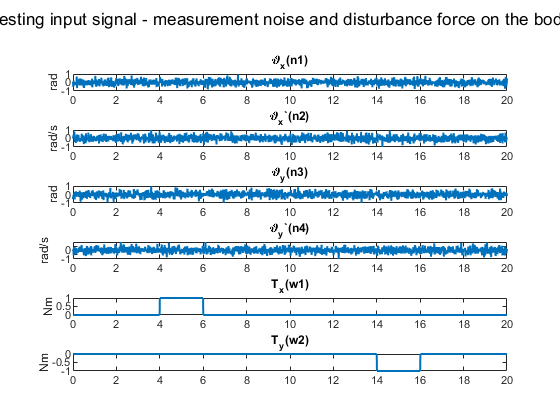

figure(200);
state_var_names = {'\vartheta_x', '\vartheta_x`','\vartheta_y', '\vartheta_y`'};
for i = 1:4
    subplot(6,1,i);
    plot(t_d,dist(i,:),'LineWidth',1.5);
    hold on
    title(strcat(state_var_names{i},'(n',num2str(i),')'))
    if mod(i,2)
        ylabel('rad')
    else
        ylabel('rad/s')
    end
end
w_names={'T_x','T_y'};
for i = 1:2
    subplot(6,1,4+i);
    plot(t_d,dist(4+i,:),'LineWidth',1.5);
    hold on
    title(strcat(w_names{i},'(w',num2str(i),')'))
    ylabel('Nm')
end
sgtitle('Testing input signal - measurement noise and disturbance force on the body')

## Creating the factorial representaion

%% disturbance matrix
B_w = fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
% noise matrix
B_n = zeros(10,4);
% measurement noise variance 1 degree 
D_n = 0.5/180*pi*eye(10,4); 
% input D matrix
D_u = zeros(10,5);
C_y = [G_n.c; zeros(3,10)];
D_y = [D_n  D_u ; [zeros(3,6) eye(3)]];
% model for simulation using y as output
P = ss(G_n.a, [B_n B_w G_n.b], [C_y; G_n.c], [ D_y; [D_n D_u] ]);

% worst case model
% disturbance matrix
B_w_wcu = fW(rK_n, rW_n, rA_n, wcu.l, mAW_n, mK_n, wcu.A_ThetaAWx, wcu.A_ThetaAWy, wcu.A_ThetaAWz, wcu.ThetaKi, wcu.ThetaWi);
% model for simulation using y as output
P_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_y; wcu.G.c], [ D_y; [D_n D_u]]);

% scaled models for h-infinty controller optimisation
H_lqr = lft(P,-K_lqr);
W = ones(1,13);
for i=1:13
   W(i) = max(min(1/hinfnorm(H_lqr(i,:)),100),1);
end
C_z = [diag(W(1:10)); zeros(3,10)];
D_z = [D_n  D_u ; [zeros(3,6) diag(W(11:13))]];
% model for h-infinity synthesis containing z output
Pz = ss(G_n.a, [B_n B_w G_n.b], [C_z; G_n.c], [ D_z; [D_n D_u] ]);
% model for h-infinity synthesis containing z output
Pz_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_z; wcu.G.c], [ D_z; [D_n D_u]]);

## Initial LQR disturbance rejection

Compariosn of linear and nonliner performcane using nominal and worst case parameters

kill_figures([201,202,203,204]);

Figure 201 not opened
Figure 202 not opened
Figure 203 not opened
Figure 204 not opened


% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_n,-K_lqr,dist,t_d,P,201,202);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 53.272422 seconds.


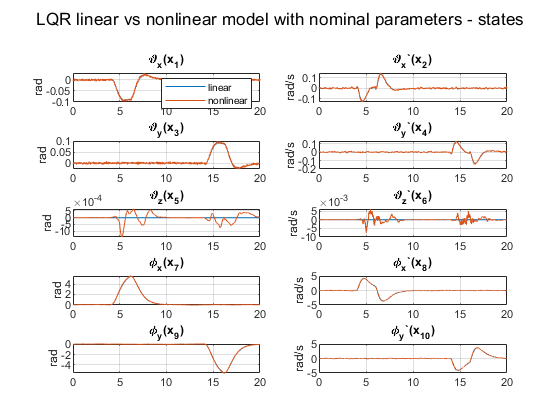

figure(201)
sgtitle('LQR linear vs nonlinear model with nominal parameters - states')

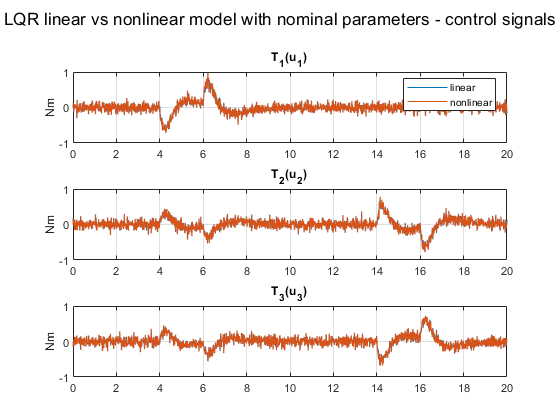

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 40.622816 seconds.


figure(202)
sgtitle('LQR linear vs nonlinear model with nominal parameters - control signals')
% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_wcu,-K_lqr,dist,t_d,P_wc,203,204);

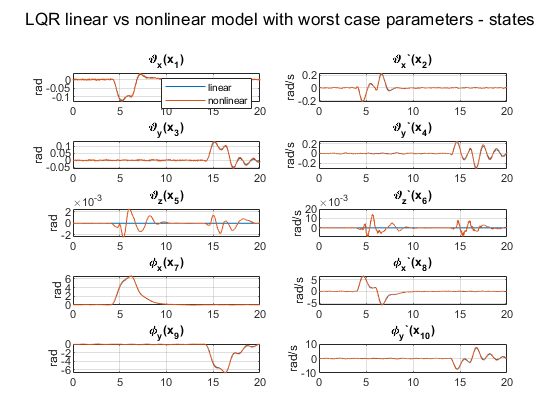

figure(203)
sgtitle('LQR linear vs nonlinear model with worst case parameters - states')

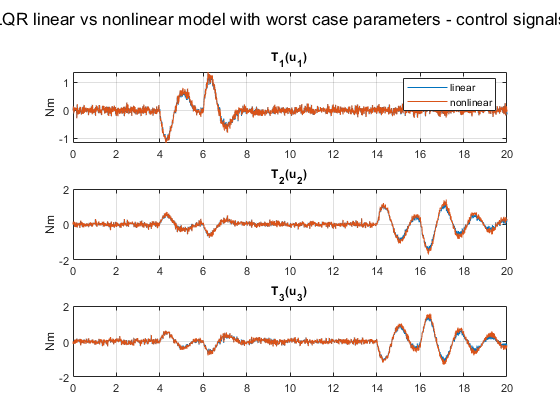

figure(204)
sgtitle('LQR linear vs nonlinear model with worst case parameters - control signals')

### Singular value plot for disturbance rejection fonominal and worst case model

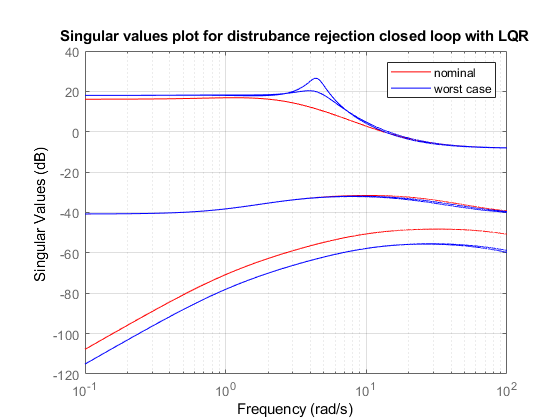

% plot singular values of distrurbance rejection loop
figure(301)
sigma(lft(P,-K_lqr),'r',lft(P_wc,-K_lqr),'b',(0.1:0.01:100));
legend('nominal','worst case');
grid on
title('Singular values plot for distrubance rejection closed loop with LQR')

## H-infinity controller design

Fixed structure - gain U=K*x;

%% H-infinity controller design fixed
% hinf fixed structure - gain
K_tun = realp('K_t',K_lqr);   
K_tun.Minimum = -50*ones(3,10); 
K_tun.Maximum = 50*ones(3,10);
opts = hinfstructOptions('TargetGain',0,'MaxIter',1000,'RandomStart',10,'MaxFrequency',10);
[C,gamma,info] = hinfstruct(Pz_wc,-K_tun,opts);

Final: Peak gain = 6.35, Iterations = 322
Final: Peak gain = 6.52, Iterations = 564
Final: Peak gain = 6.53, Iterations = 678
Final: Peak gain = 6.39, Iterations = 686
Final: Peak gain = 6.7, Iterations = 519
Final: Peak gain = 6.36, Iterations = 490
Final: Peak gain = 6.37, Iterations = 582
Final: Peak gain = 6.47, Iterations = 650
Final: Peak gain = 6.35, Iterations = 494
Final: Peak gain = 6.38, Iterations = 527
Final: Failed to enforce closed-loop stability (max Re(s) = 1)


K_hinf = C.Blocks.K_t.Value

K_hinf =    49.9999   43.0578  -49.9958  -16.1591   42.7115   -4.5940   -0.3843    2.5548   -0.7942   -0.7764
  -44.4468  -19.0091   50.0000   20.9802  -50.0000  -18.1558    0.6559   -1.7117    0.8187    0.8818
   -5.0943  -28.5107  -50.0000  -25.1189  -29.1846   12.4179    0.6576   -1.4275   -0.5884   -1.3849


## **Comparison of H-infinity and LQR **

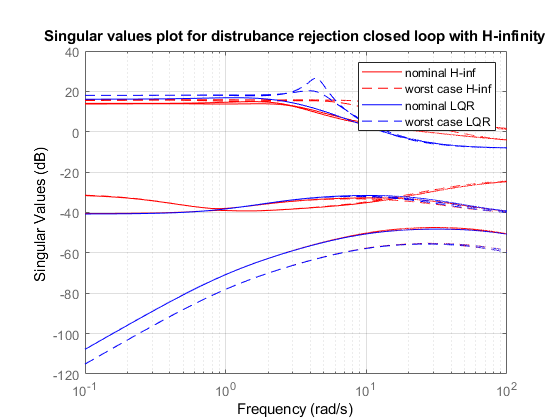

% plot singular values of distrurbance rejection loop
figure(302)
sigma(lft(P,-K_hinf),'r',lft(P_wc,-K_hinf),'--r',lft(P,-K_lqr),'b',lft(P_wc,-K_lqr),'--b',(0.1:0.01:100));
legend('nominal H-inf','worst case H-inf','nominal LQR','worst case LQR');
grid on
title('Singular values plot for distrubance rejection closed loop with H-infinity')

## Complarison H-infinity and LQR linear models

kill_figures([303,304,305,306]);

Figure 303 not opened
Figure 304 not opened
Figure 305 not opened
Figure 306 not opened


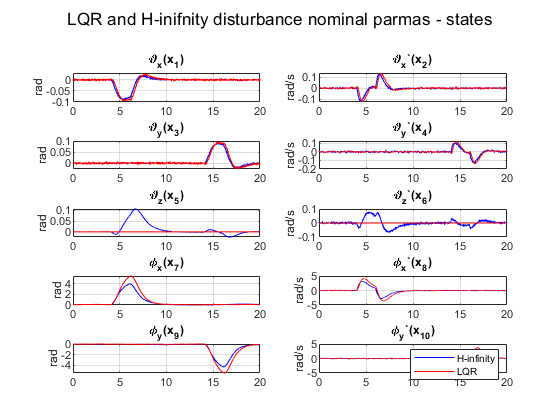

linsim(lft(P,-K_hinf),'b',dist,t_d,303,304);
linsim(lft(P,-K_lqr),'r',dist,t_d,303,304);
figure(303)
sgtitle('LQR and H-inifnity disturbance nominal parmas - states')
legend('H-infinity','LQR')

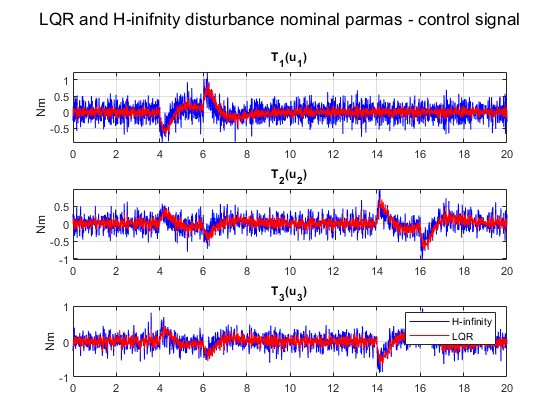

figure(304)
sgtitle('LQR and H-inifnity disturbance nominal parmas - control signal')
legend('H-infinity','LQR')

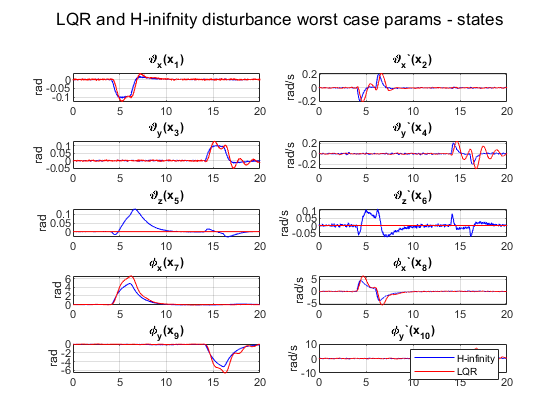

linsim(lft(P_wc,-K_hinf),'b',dist,t_d,305,306);
linsim(lft(P_wc,-K_lqr),'r',dist,t_d,305,306);
figure(305)
sgtitle('LQR and H-inifnity disturbance worst case params - states')
legend('H-infinity','LQR')

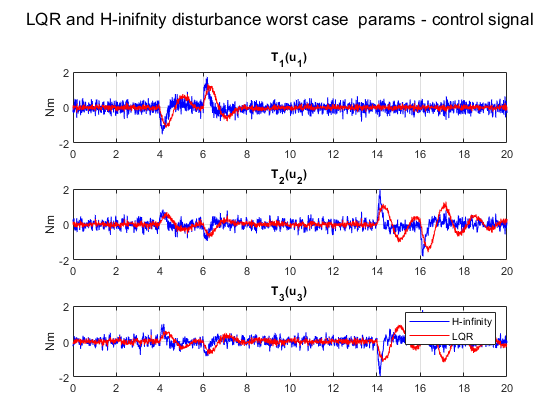

figure(306)
sgtitle('LQR and H-inifnity disturbance worst case  params - control signal')
legend('H-infinity','LQR')

### Bode diagram of comparison 

kill_figures([312,311]);

Figure 312 not opened
Figure 311 not opened


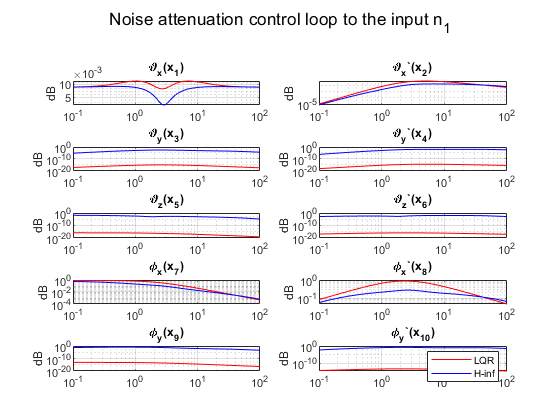

H_lqr = lft(P,-K_lqr);
H_hinf = lft(P,-K_hinf);
bodemg(H_lqr(1:10,1),'r',311);
hold on
bodemg(H_hinf(1:10,1),'b',311);
legend('LQR', 'H-inf')
sgtitle('Noise attenuation control loop to the input n_1');

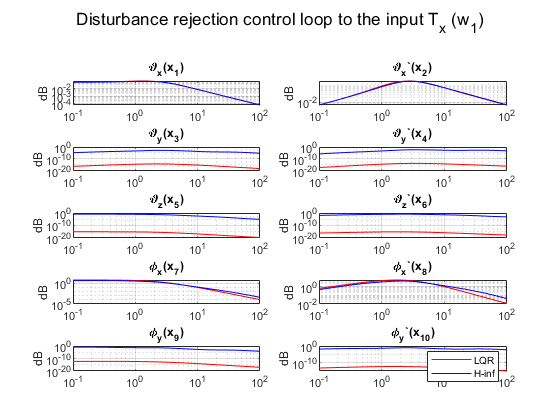


bodemg(H_lqr(1:10,5),'r',312);
hold on
bodemg(H_hinf(1:10,5),'b',312);
legend('LQR', 'H-inf')
sgtitle('Disturbance rejection control loop to the input T_x (w_1)');

## Complarison H-infinity and nonlinear model

kill_figures([307,308,309,310]);

Figure 307 not opened
Figure 308 not opened
Figure 309 not opened
Figure 310 not opened


nlsim(@nlin_model_n,-K_hinf,dist,t_d,P_wc,307,308);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 53.901075 seconds.


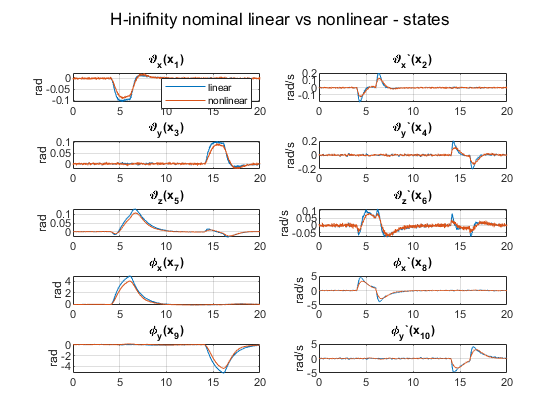

figure(307);
sgtitle('H-inifnity nominal linear vs nonlinear - states')

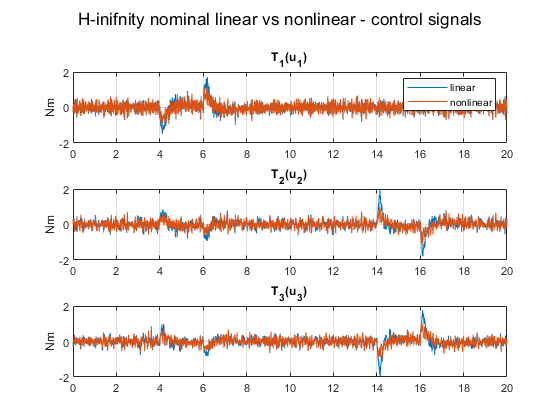

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 57.205975 seconds.


figure(308)
sgtitle('H-inifnity nominal linear vs nonlinear - control signals')
nlsim(@nlin_model_wcu,-K_hinf,dist,t_d,P,309,310);

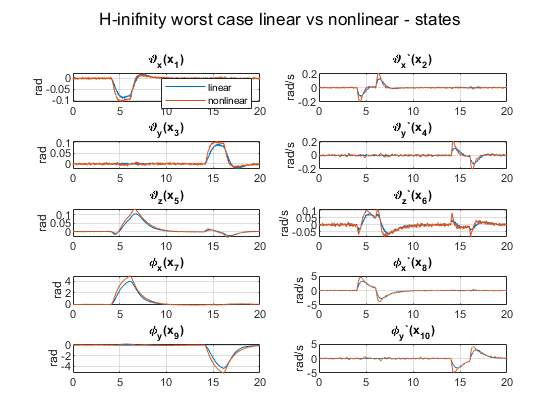

figure(309)
sgtitle('H-inifnity worst case linear vs nonlinear - states')

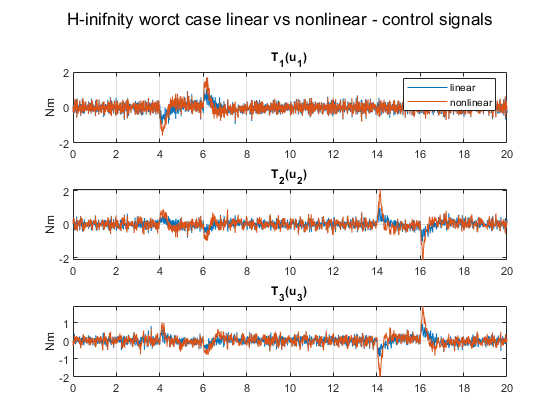

figure(310)
sgtitle('H-inifnity worct case linear vs nonlinear - control signals')

## State space H-infinity controller 

State space controller

%% H-infinity controller 
ns = 3;
A_tun = realp('A_t',rand(ns,ns));  
A_tun.Minimum = -50*ones(ns,ns); 
A_tun.Maximum = 50*ones(ns,ns);
B_tun = realp('B_t',rand(ns,10));   
B_tun.Minimum = -50*ones(ns,10); 
B_tun.Maximum = 50*ones(ns,10);
C_tun = realp('C_t',rand(3,ns));   
C_tun.Minimum = -50*ones(3,ns); 
C_tun.Maximum = 50*ones(3,ns);
D_tun = realp('D_t',rand(3,10));   
D_tun.Minimum = -50*ones(3,10); 
A_tD_tunun.Maximum = 50*ones(3,10);
opts = hinfstructOptions('TargetGain',0,'MaxIter',1000,'RandomStart',10,'MaxFrequency',10);
K_tun = ss(A_tun,B_tun,C_tun,D_tun);
[C,gamma,info] = hinfstruct(Pz_wc,K_tun,opts);

Final: Peak gain = 5.76, Iterations = 965
Final: Peak gain = 10.3, Iterations = 405
Final: Peak gain = 9.85, Iterations = 921
Final: Peak gain = 13.8, Iterations = 342
Final: Peak gain = 7.26, Iterations = 769
Final: Peak gain = 18.1, Iterations = 397
Final: Peak gain = 10, Iterations = 598
Final: Peak gain = 9.96, Iterations = 793
Final: Peak gain = 23.8, Iterations = 405
Final: Peak gain = 11.4, Iterations = 835
Final: Peak gain = 14, Iterations = 221


K_hinf_ss = ss(C.Blocks.A_t.Value,C.Blocks.B_t.Value,C.Blocks.C_t.Value,C.Blocks.D_t.Value)


K_hinf_ss =
 
  A = 
            x1       x2       x3
   x1    -4.37    5.823  -0.3046
   x2   -1.655    5.308    4.282
   x3    7.205   -14.02   -6.481
 
  B = 
             u1        u2        u3        u4        u5        u6
   x1       -50    -20.73    -48.53    -49.83    -49.84        50
   x2    -14.94    -17.03     40.44     9.464     49.92     33.51
   x3     39.62      1.83    -2.909     47.13    -36.53    -36.29
 
             u7        u8        u9       u10
   x1     1.382   -0.2917     14.14   -0.5971
   x2      3.17    -1.102      22.4    0.2381
   x3    -6.888  -0.06474    -49.94   -0.6838
 
  C = 
           x1      x2      x3
   y1   3.698   6.483  -0.331
   y2  -7.034   1.316  -1.872
   y3  0.8326  -1.866   5.144
 
  D = 
           u1      u2      u3      u4      u5      u6      u7
   y1   1.574     -50   -47.6     -50   111.7    14.1   1.554
   y2  -17.45   44.87  -49.37     -50  -47.72   15.91   0.205
   y3   23.79   8.489     138   106.4  -48.62   -18.3   1.538
 

## Comparison LQR and H-inifnity state space

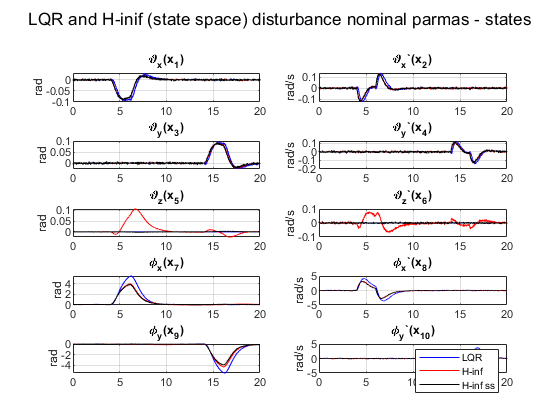

kill_figures([404,405,406,407]);
linsim(lft(P,-K_lqr),'b',dist,t_d,404,405);
linsim(lft(P,-K_hinf),'r',dist,t_d,404,405);
linsim(lft(P,K_hinf_ss),'k',dist,t_d,404,405);
figure(404)
sgtitle('LQR and H-inif (state space) disturbance nominal parmas - states')
legend('LQR','H-inf','H-inf ss')

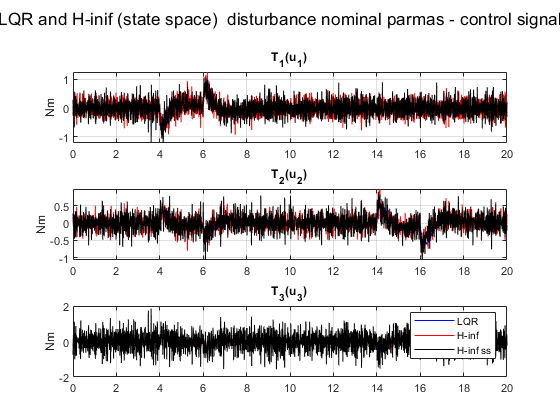

figure(405)
sgtitle('LQR and H-inif (state space)  disturbance nominal parmas - control signal')
legend('LQR','H-inf','H-inf ss')

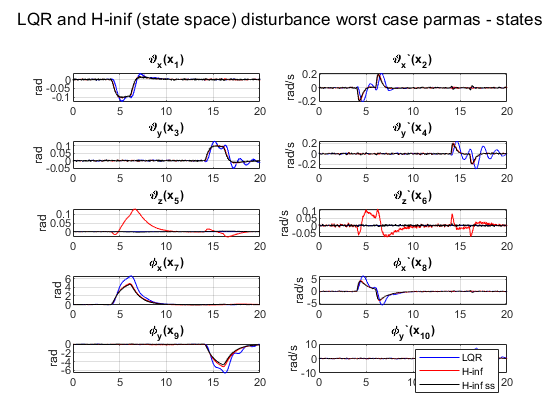

linsim(lft(P_wc,-K_lqr),'b',dist,t_d,406,407);
linsim(lft(P_wc,-K_hinf),'r',dist,t_d,406,407);
linsim(lft(P_wc,K_hinf_ss),'k',dist,t_d,406,407);
figure(406)
sgtitle('LQR and H-inif (state space) disturbance worst case parmas - states')
legend('LQR','H-inf','H-inf ss')

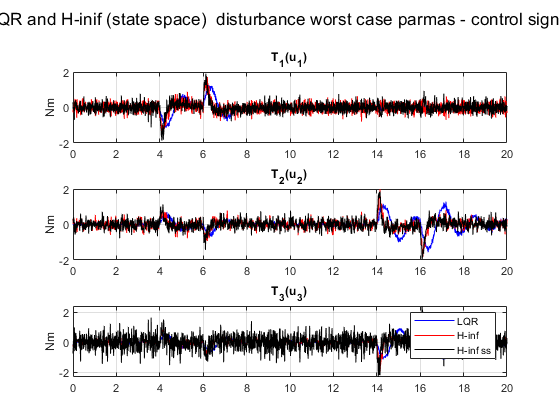

figure(407)
sgtitle('LQR and H-inif (state space)  disturbance worst case parmas - control signal')
legend('LQR','H-inf','H-inf ss')

## Complarison H-infinity and nonlinear model

kill_figures([507,508,509,510]);
nlsim(@nlin_model_n,K_hinf_ss,dist,t_d,P_wc,507,508);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 38.449356 seconds.


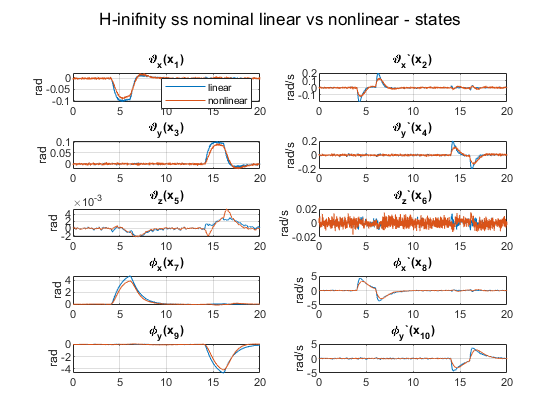

figure(507);
sgtitle('H-inifnity ss nominal linear vs nonlinear - states')
hold off;

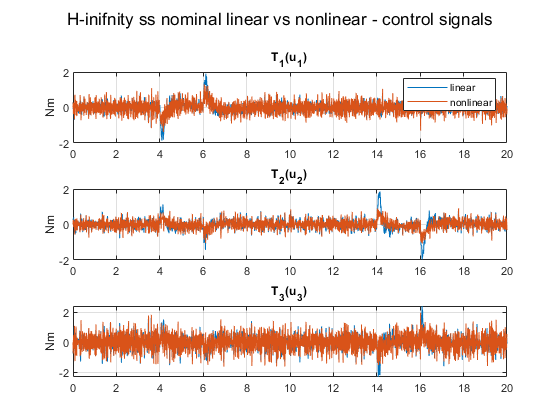

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 39.601003 seconds.


figure(508)
sgtitle('H-inifnity ss nominal linear vs nonlinear - control signals')
hold off;
nlsim(@nlin_model_wcu,K_hinf_ss,dist,t_d,P,509,510);

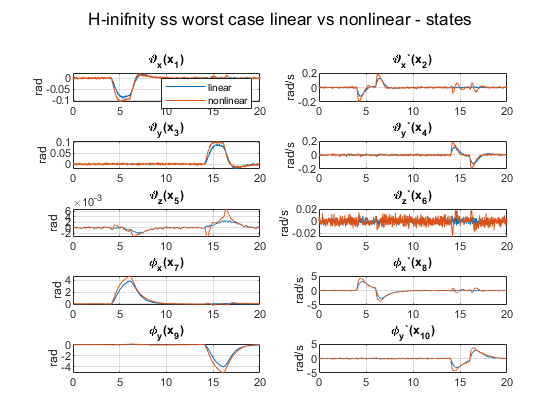


figure(509)
sgtitle('H-inifnity ss worst case linear vs nonlinear - states')

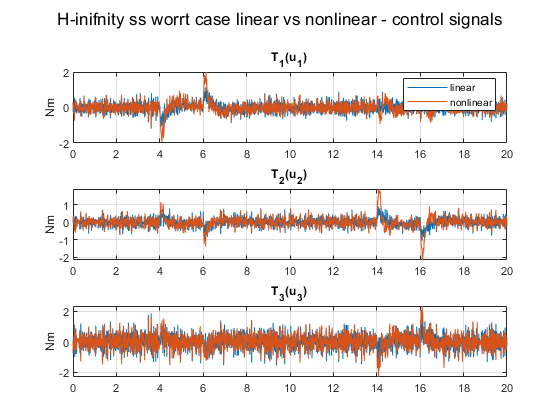

figure(510)
sgtitle('H-inifnity ss worrt case linear vs nonlinear - control signals')

## Bode diagram of LQR, H-infinity gain and H-infinity state space

We can see that state space H-infinity controller has lowest gain for almost all the transfrer functions on the plot making it the most robustly stable one.

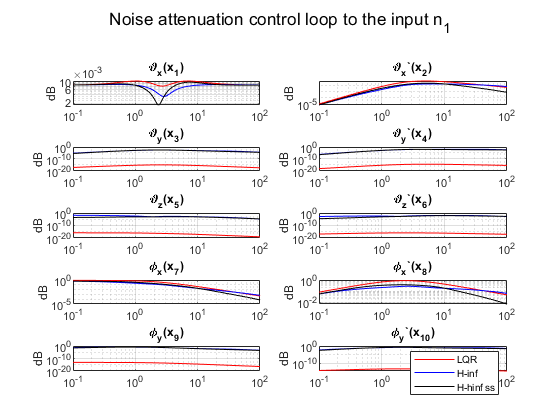

kill_figures([506,512]);
figure(506)
H_hinf_ss = lft(P,K_hinf_ss);
bodemg(H_lqr(1:10,1),'r',506);
hold on
bodemg(H_hinf(1:10,1),'b',506);
bodemg(H_hinf_ss(1:10,1),'k',506);
legend('LQR', 'H-inf', 'H-hinf ss')
sgtitle('Noise attenuation control loop to the input n_1');

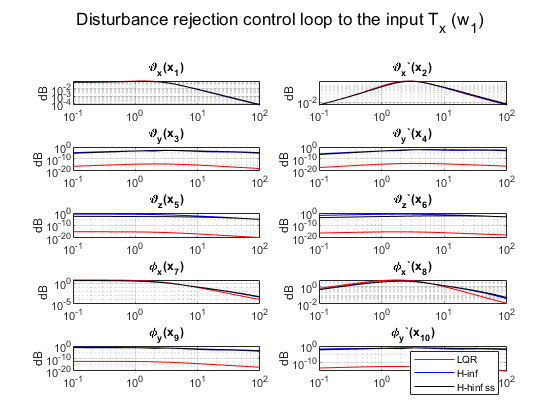

bodemg(H_lqr(1:10,5),'r',512);
hold on
bodemg(H_hinf(1:10,5),'b',512);
bodemg(H_hinf_ss(1:10,5),'k',512);
legend('LQR', 'H-inf','H-hinf ss')
sgtitle('Disturbance rejection control loop to the input T_x (w_1)');

## H-infintiy norms for nominal and worst case parameter linear model comparison of LQR, fixed H-inifnity and state space H-Infinity controller

hinfnorm(lft(P,-K_lqr))

ans = 6.9632

hinfnorm(lft(P,-K_hinf))

ans = 5.5652

hinfnorm(lft(P,K_hinf_ss))

ans = 5.1548

hinfnorm(lft(P_wc,-K_lqr))

ans = 21.0884

hinfnorm(lft(P_wc,-K_hinf))

ans = 6.2838

hinfnorm(lft(P_wc,K_hinf_ss))

ans = 5.6816

## Stability margins for nominal and worst case parameter linear model comparison of LQR, fixed H-inifnity and state space H-Infinity controller

diskmargin(G_n,K_lqr)

ans = struct with fields:
     GainMargin: [0.8536 1.1715]
    PhaseMargin: [-9.0299 9.0299]
     DiskMargin: 0.1579
     LowerBound: 0.1579
     UpperBound: 0.1582
      Frequency: 3.5389


diskmargin(G_n,K_hinf)

ans = struct with fields:
     GainMargin: [0.8439 1.1849]
    PhaseMargin: [-9.6763 9.6763]
     DiskMargin: 0.1693
     LowerBound: 0.1693
     UpperBound: 0.1696
      Frequency: 3.0979


diskmargin(G_n,-K_hinf_ss)

ans = struct with fields:
     GainMargin: [0.9003 1.1107]
    PhaseMargin: [-6.0048 6.0048]
     DiskMargin: 0.1049
     LowerBound: 0.1049
     UpperBound: 0.1051
      Frequency: 1.8334


diskmargin(wcu.G,K_lqr)

ans = struct with fields:
     GainMargin: [0.9679 1.0331]
    PhaseMargin: [-1.8665 1.8665]
     DiskMargin: 0.0326
     LowerBound: 0.0326
     UpperBound: 0.0326
      Frequency: 4.4068


diskmargin(wcu.G,K_hinf)

ans = struct with fields:
     GainMargin: [0.9307 1.0745]
    PhaseMargin: [-4.1108 4.1108]
     DiskMargin: 0.0718
     LowerBound: 0.0718
     UpperBound: 0.0719
      Frequency: 10.8854


diskmargin(wcu.G,-K_hinf_ss)

ans = struct with fields:
     GainMargin: [0.9484 1.0544]
    PhaseMargin: [-3.0320 3.0320]
     DiskMargin: 0.0529
     LowerBound: 0.0529
     UpperBound: 0.0530
      Frequency: 8.7176


## Closed loop singular value plot comparison

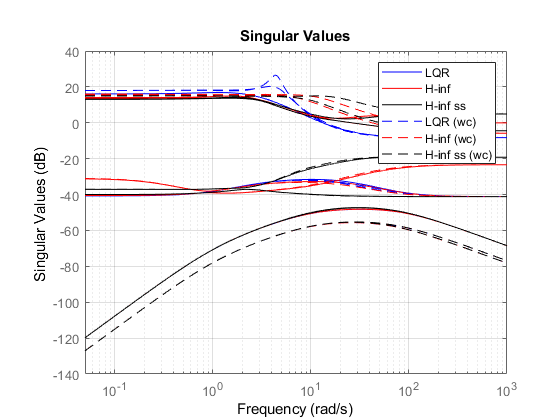

% plot singular values of distrurbance rejection loop
figure(520)
sigma(lft(P,-K_lqr),'b',lft(P,-K_hinf),'r',lft(P,K_hinf_ss),'k',lft(P_wc,-K_lqr),'--b',lft(P_wc,-K_hinf),'--r',lft(P_wc,K_hinf_ss),'--k',(0.05:0.01:1000));
legend('LQR','H-inf','H-inf ss','LQR (wc)','H-inf (wc)','H-inf ss (wc)');
grid on;